param;

% First Stage, Medium 1 

%(k^2-kx^2)*
Bx1=(k^2-kx^2)*cos(kx*(xh-Nx)).*sin(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(1)^2*Er_air);
By1=ky*kx*sin(kx*(xh-Nx)).*cos(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(1)^2*Er_air);
%ky*kx*

% Second Stage, Medium 1
[Sx,Hsx,Hmx,Hix,Hzx] = Sx2d2(1,2,-1);
[Sy,Hsy,Hmy,Hiy,Hzy] = Sy2d2(1,2,-1);
% [Sx,Hsx,Hmx,Hix,Hzx] = Sx2d();
% [Sy,Hsy,Hmy,Hiy,Hzy] = Sy2d();
Hi=Hix+Hiy;
Hm=Hmx+Hmy;
Hx=Hzx+Hzy;
Hs=Hsx+Hsy;
for i=1:1:max(m)    
%   Axy1(:,1,i)=[(Sx(1,1,i)).*Bx1(i)+(Sy(1,2,i)).*By1(i);(Sx(2,1,i)).*Bx1(i)+(Sy(2,2,i)).*By1(i)];
    Axy1(:,:,i)=[(Sx(1,1,i)+Sx(2,1,i)).*Bx1(i)+Bx1o(i).*Hs(i);(Sy(1,1,i)+Sy(2,1,i)).*By1(i)+By1o(i).*Hs(i)]; 
   [Axy1_1,Axy1_2]=meshgrid(Axy1(1,i),Axy1(2,i));

end   



%Third Stage, Medium 1

Amn1=fmt(Axy1(1,:),Axy1(2,:),W,L,Qmn1);



%Fourth Stage, Medium 1
RC_1 = RC1_2d(Er_air);

for i=1:1:max(m)
    Bmn1(:,:,i)=[RC_1(1,1,i).*Amn1(1,i);RC_1(2,2,i).*Amn1(2,i)];
end    



%Fith Stage, Medium 1

BXY1=ifmt(Bmn1,W,L,Qmn1);
[BXY1_1,BXY1_2]=meshgrid(BXY1(1,:),BXY1(2,:));

% First Stage, Medium 2
%(k^2-kx^2)*
Bx2=(k^2-kx^2)*cos(kx*(xh-Nx)).*sin(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(2)^2*Er);
By2=ky*kx*sin(kx*(xh-Nx)).*cos(ky*(yh-Ny))./(wFreq*Eo^2*Z0i(2)^2*Er);
%ky*kx*

% Second Stage, Medium 2


for i=1:1:max(m)     
%     Axy2(:,1,i)=[(Sx(1,1,i)).*Bx2(i)+(Sy(1,2,i)).*By2(i);(Sx(2,1,i)).*Bx2(i)+(Sy(2,2,i)).*By2(i)];
      Axy2(:,:,i)=[(Sx(1,2,i)+Sx(2,2,i)).*Bx2(i)+Bx1o(i).*Hs(i);(Sy(1,2,i)+Sy(2,2,i)).*By2(i)+By2o(i).*Hs(i)];
      [Axy2_1,Axy2_2]=meshgrid(Axy2(1,i),Axy2(2,i));
end



%Third Stage, Medium 2
Amn2=fmt(Axy2(1,:),Axy2(2,:),W,L,Qmn2);

%Fourth Stage, Medium 2
RC_2 = RC2_2d(Er);
for i=1:1:max(m)    
    Bmn2(:,:,i)=[RC_2(1,1,i)*Amn2(1,i);RC_2(2,2,i).*Amn2(2,i)];
end


%Fith Stage, Medium 2

BXY2=ifmt(Bmn2,W,L,Qmn2);
[BXY2_1,BXY2_2]=meshgrid(BXY2(1,:),BXY2(2,:));


%Grid

ea1=sqrt(Z0i(1)).*Axy1_1+sqrt(Z0i(1)).*Axy1_2;
ea2=sqrt(Z0i(2)).*Axy2_1+sqrt(Z0i(2)).*Axy2_2;

eb1=sqrt(Z0i(1)).*BXY1_1+sqrt(Z0i(1)).*BXY1_2;
eb2=sqrt(Z0i(2)).*BXY2_1+sqrt(Z0i(2)).*BXY2_2;

ja1=Axy1_1/sqrt(Z0i(1))+Axy1_2/sqrt(Z0i(1));
ja2=Axy2_1/sqrt(Z0i(2))+Axy2_2/sqrt(Z0i(2));

jb1=BXY1_1/sqrt(Z0i(1))+BXY1_2/sqrt(Z0i(1));
jb2=BXY2_1/sqrt(Z0i(2))+BXY2_2/sqrt(Z0i(2));

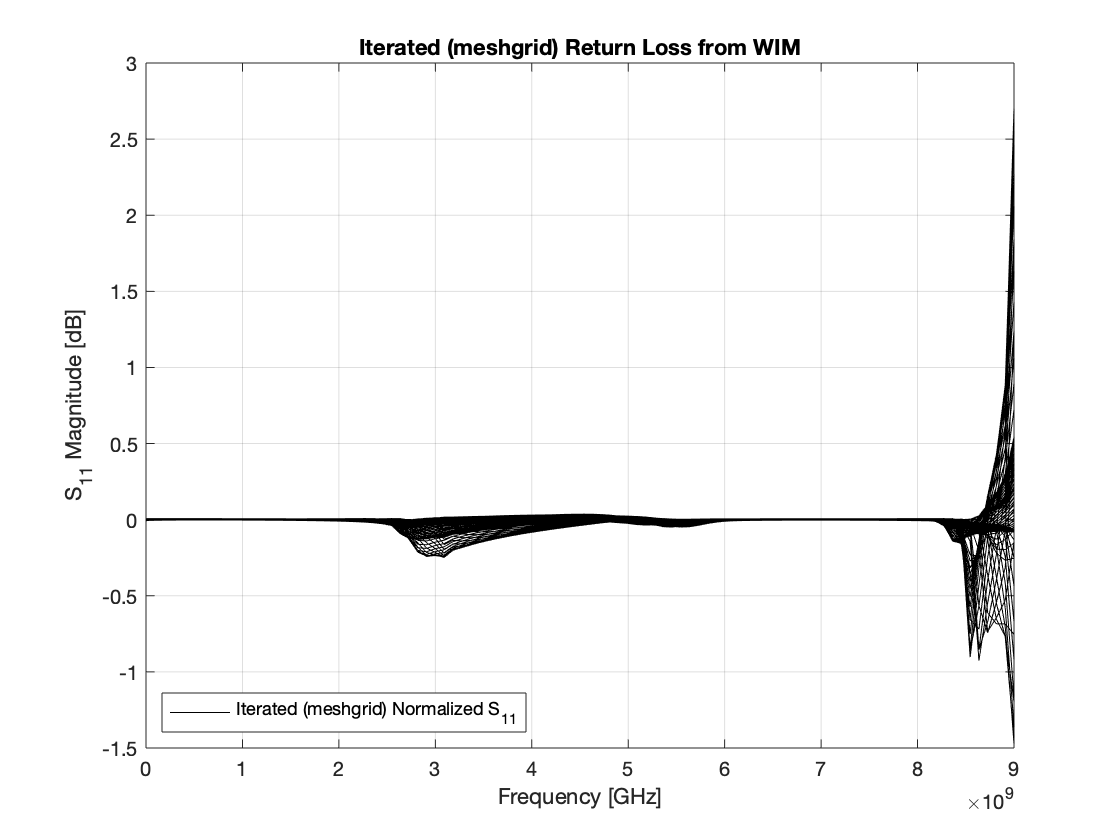

n_ea=sqrt(abs(ea1).^2+abs(ea2).^2);
n_eb=sqrt(abs(eb1).^2+abs(eb2).^2);
n_ja=sqrt(abs(ja1).^2+abs(ja2).^2);
n_jb=sqrt(abs(jb1).^2+abs(jb2).^2);
%%%
% n_ea=sqrt(real(ea1).^2+real(ea2).^2);
% n_eb=sqrt(real(eb1).^2+real(eb2).^2);
% n_ja=sqrt(real(ja1).^2+real(ja2).^2);
% n_jb=sqrt(real(jb1).^2+real(jb2).^2);
%%%
Exy1=(ea1+ea2)./n_ea+(eb1+eb2)./n_eb;
Jxy1=(ja1+ja2)./n_ja-(jb1+jb2)./n_jb;
Z1=Exy1./Jxy1;
Rcoef1=(-Z0+Z1)./(Z1+Z0);
RL1=20*log(abs(Rcoef1));
%%%%
fl=linspace(0,9e9,T);
plot(fl,real(RL1),'k')
grid
legend({'Iterated (meshgrid) Normalized S_{11}'},'Location','South West')
title('Iterated (meshgrid) Return Loss from WIM')
xlabel('Frequency [GHz]')
ylabel('S_{11} Magnitude [dB]')

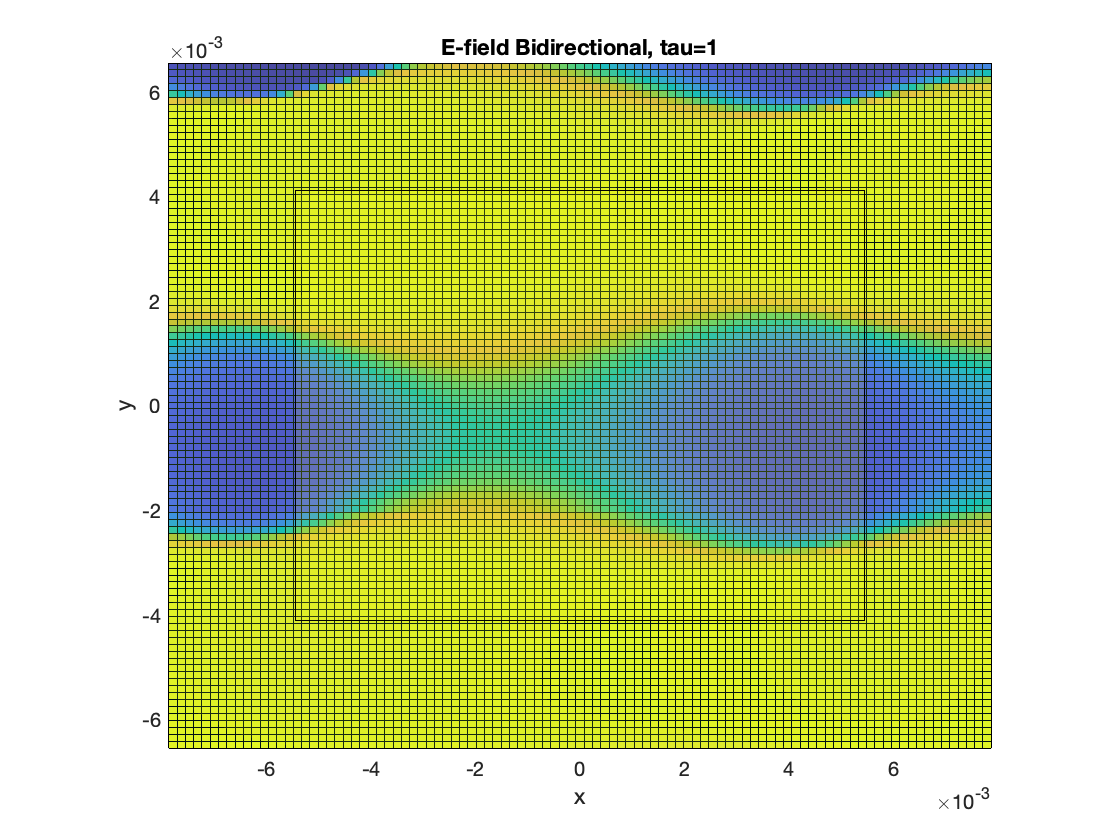

figure(4)
surf(xh,yh,real((Exy1/2000)))
showpatch()
axis equal
view(2)
title('E-field Bidirectional, tau=1')

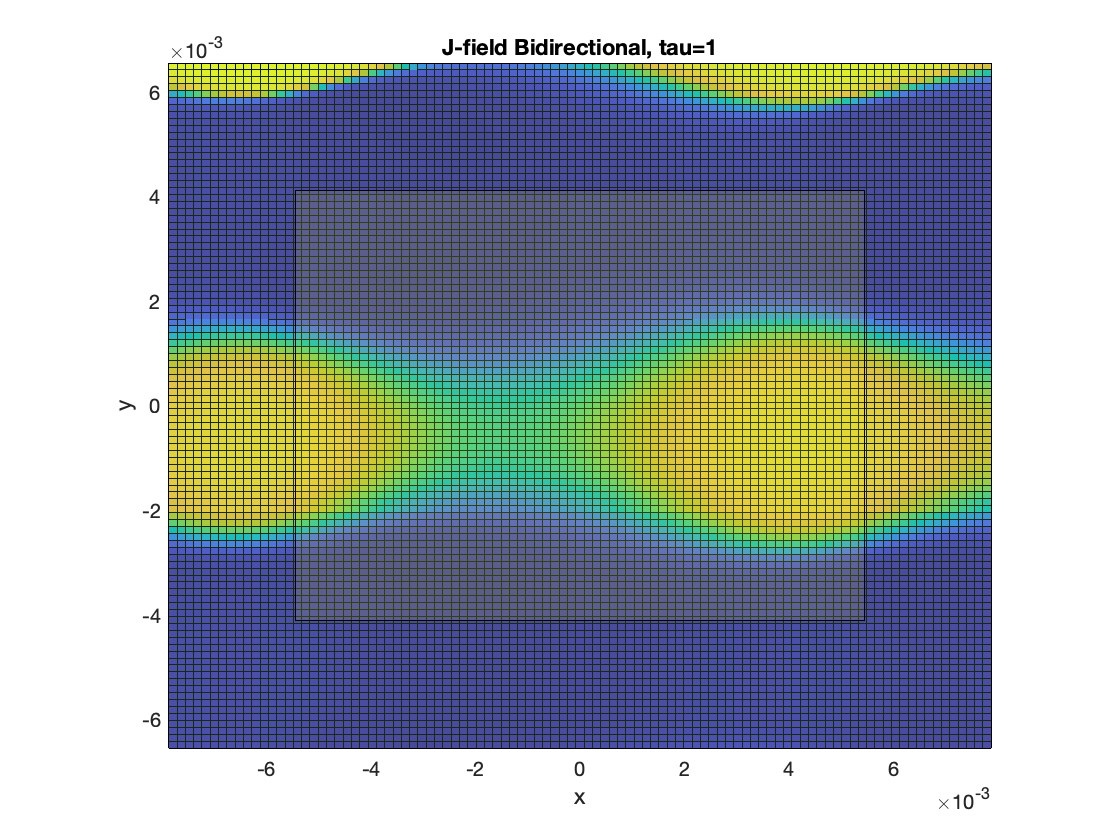

figure(5)
surf(xh,yh,real((Jxy1/2000)))
showpatch()
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
view(2)
title('J-field Bidirectional, tau=1')

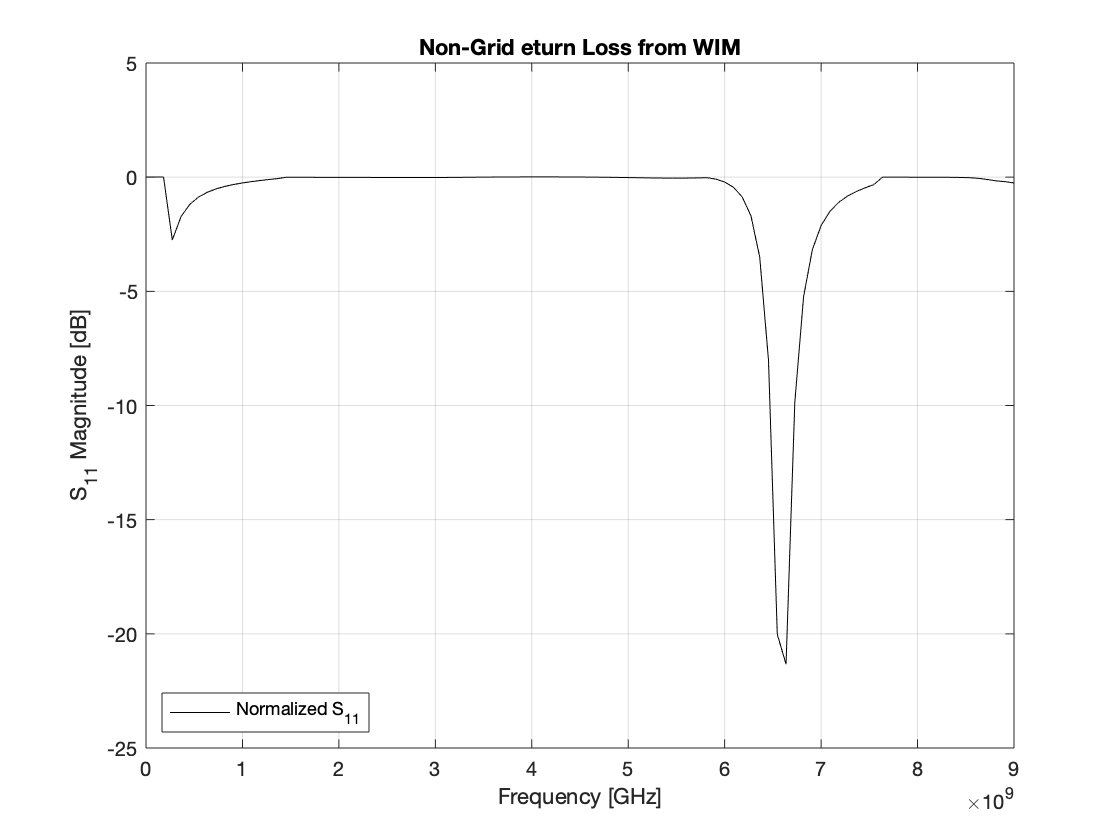

%NON-GRID PLOTS
ea1n=sqrt(Z0i(1)).*Axy1(1,:)+sqrt(Z0i(1)).*Axy1(2,:);
ea2n=sqrt(Z0i(2)).*Axy2(1,:)+sqrt(Z0i(2)).*Axy2(2,:);

eb1n=sqrt(Z0i(1)).*BXY1(1,:)+sqrt(Z0i(1)).*BXY1(2,:);
eb2n=sqrt(Z0i(2)).*BXY2(1,:)+sqrt(Z0i(2)).*BXY2(2,:);

ja1n=Axy1(1,:)/sqrt(Z0i(1))+Axy1(2,:)/sqrt(Z0i(1));
ja2n=Axy2(1,:)/sqrt(Z0i(2))+Axy2(2,:)/sqrt(Z0i(2));

jb1n=BXY1(1,:)/sqrt(Z0i(1))+BXY1(2,:)/sqrt(Z0i(1));
jb2n=BXY2(1,:)/sqrt(Z0i(2))+BXY2(2,:)/sqrt(Z0i(2));
%%%%
n_ean=sqrt(abs(ea1n).^2+abs(ea2n).^2);
n_ebn=sqrt(abs(eb1n).^2+abs(eb2n).^2);
n_jan=sqrt(abs(ja1n).^2+abs(ja2n).^2);
n_jbn=sqrt(abs(jb1n).^2+abs(jb2n).^2);
%%%%%
% n_ean=sqrt(real(ea1n).^2+real(ea2n).^2);
% n_ebn=sqrt(real(eb1n).^2+real(eb2n).^2);
% n_jan=sqrt(real(ja1n).^2+real(ja2n).^2);
% n_jbn=sqrt(real(jb1n).^2+real(jb2n).^2);

%%%%
Exy1n=(ea1n+ea2n)./n_ean+(eb1n+eb2n)./n_ebn;
Jxy1n=(ja1n+ja2n)./n_jan-(jb1n+jb2n)./n_jbn;
%%%%
Z1n=Exy1n./Jxy1n;
Rcoef1n=(Z0-Z1n)./(Z1n+Z0);
RL1n=20*log(abs(Rcoef1n));
%%%%
fl=linspace(0,9e9,T);
plot(fl,real(RL1n),'k')
grid
legend({'Normalized S_{11}'},'Location','South West')
title('Non-Grid eturn Loss from WIM')
xlabel('Frequency [GHz]')
ylabel('S_{11} Magnitude [dB]')

% param2D;
% [H_mx,H_ix,H_sx,H_zx,H_my,H_iy,H_sy,H_zy] = H();
% [Hix,Hiy]=meshgrid(H_ix,H_iy);
% [Hmx,Hmy]=meshgrid(H_mx,H_my);
% [Hsx,Hsy]=meshgrid(H_sx,H_sy);
% [Hzx,Hzy]=meshgrid(H_zx,H_zy);
% 
% Hm=Hmx+Hmy;
% Hm(1:19,17:84)=0;
% Hm(82:100,17:84)=0;
% Hm(20:82,1:15)=0;
% Hm(20:82,85:100)=0;
% 
% Hz=Hzx+Hzy;
% Hz(1:19,17:84)=0;
% Hz(82:100,17:84)=0;
% Hz(20:82,1:15)=0;
% Hz(20:82,85:100)=0;
% 
% Hi=Hix+Hiy;
% Hi(1:19,1:100)=1;
% Hi(82:100,1:100)=1;
% Hi(20:81,1:16)=1;
% Hi(20:81,86:100)=1;
% 
% Hs=Hsx+Hsy;
% Hs(35,50:51)=1;
% Hs(1:100,1:49)=0;
% Hs(1:100,52:100)=0;
% Hs(1:34,:)=0;
% Hs(36:100,:)=0;
% 
% figure()
% surf(xh,yh,Hi)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% title('H step-function for dielectric')
% 
% 
% surf(xh,yh,Hm)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% title('H step-function for metal')
% 
% surf(xh,yh,Hs)
% xlabel('x')
% ylabel('y')
% zlabel('z')
% 
% xlabel('x')
% ylabel('y')
% zlabel('z')
% title('H step-function for source')
